**VECTORS AND ARRAYS**

Ex 1. Definition of vectors

v1 = 2.^[0:10]

v1 =            1           2           4           8          16          32          64         128         256         512        1024


v2 = cos (pi ./ [1:10])'

v2 =    -1.0000
    0.0000
    0.5000
    0.7071
    0.8090
    0.8660
    0.9010
    0.9239
    0.9397
    0.9511


format short g, v3 = 0.1 .* 2 .^ [0:-1:-5]

v3 =           0.1         0.05        0.025       0.0125      0.00625     0.003125


Ex 2. Definition of array B

b = [1:7; 9:-2:-3; 2.^(2:8)]

b =      1     2     3     4     5     6     7
     9     7     5     3     1    -1    -3
     4     8    16    32    64   128   256


Ex 3. 

%Sum 5 and 7 columns of B 
b31 = b * [0 0 0 0 1 0 1]'

b31 =     12
    -2
   320


%Last row of B
b32 = [0 0 1] * b

b32 =      4     8    16    32    64   128   256


%Swap 2nd and 3rd rows of B
b33 = [1 0 0; 0 0 1; 0 1 0] * b

b33 =      1     2     3     4     5     6     7
     4     8    16    32    64   128   256
     9     7     5     3     1    -1    -3


**PLOTS**

Ex 1. Use of '@' and 'inline' commands to define and evaluate a function

x=[0:3];
% definition with @
f1=@(x) x.*sin(x)+(1/2).^(sqrt(x));
f1(x)

ans =             1       1.3415       2.1938      0.72438


% definition with 'inline'
f1_in = inline('x.*sin(x)+(1/2).^(sqrt(x))','x');
f1_in(x)

ans =             1       1.3415       2.1938      0.72438



% the same can be done for f2
f2=@(x) x.^4+log(x.^3+1);
f2(x)

ans =             0       1.6931       18.197       84.332


f2_in = inline('x.^4+log(x.^3+1)','x');
f2_in(x)

ans =             0       1.6931       18.197       84.332


Ex 2. Plot different curves in the same figure 

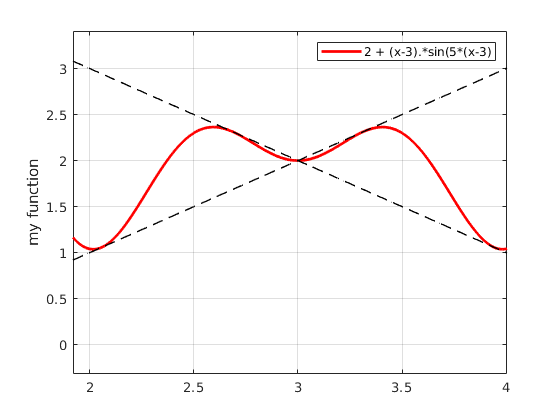

x = [0:0.01:6];
f = @(x) 2 + (x-3).*sin(5*(x-3));
plot(x,f(x),'Linewidth',2,'Color','r') 
hold on; grid on;
g = @(x) -x +5;
h = @(x) x - 1;
plot(x,g(x),'LineWidth',1,'LineStyle','--','Color','k')
plot(x,h(x),'LineWidth',1,'LineStyle','--','Color','k')
legend('2 + (x-3).*sin(5*(x-3)');

ylabel('my function')

Ex 3. Plot functions using the logarthmic scale

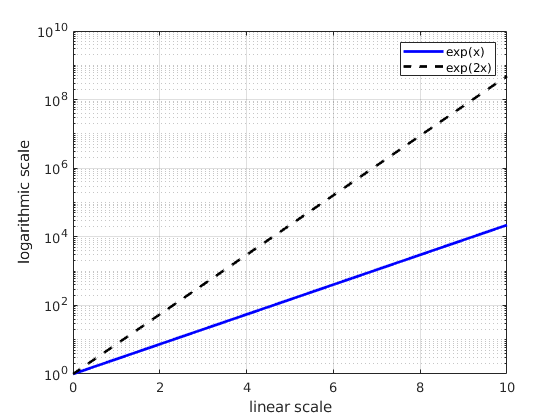

x = [0:0.01:10];
f = @(x) exp(x);
g = @(x) exp(2*x);
figure;
semilogy(x,f(x),'Linewidth',2,'Color','b') 
hold on; grid on;
semilogy(x,g(x),'LineWidth',2,'LineStyle','--','Color','k')
legend('exp(x)','exp(2x)');
xlabel('linear scale');
ylabel('logarithmic scale');

**SCRIPTS AND LOOPS**

Ex 1. Double for loop for the definition of the HIlbert matrix

a = zeros(5);
for i = 1 : 5
    for j = 1 : 5
        a(i,j) = 1/(i+j-1);
    end
end
disp(a)

            1          0.5      0.33333         0.25          0.2
          0.5      0.33333         0.25          0.2      0.16667
      0.33333         0.25          0.2      0.16667      0.14286
         0.25          0.2      0.16667      0.14286        0.125
          0.2      0.16667      0.14286        0.125      0.11111



disp(a==hilb(5))

   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1
   1   1   1   1   1



Ex 2.  Example of while loop

year = 0;
deposit = 10000;
deposit_values = deposit;
interest_rate = 1.02;
while (deposit < 1e6)
    year = year + 1;
    deposit = deposit * interest_rate + 10000;
    deposit_values = [deposit_values deposit];
end
disp(year);

    55



Ex 3. An other use of the while loop

n=1;
while ( sum([1:n]) < 88 )     
   n=n+1;
end
n

n =     13


**FUNCTIONS AND OUTPUTS**

Ex 1. Use of the funtion Is_triangle.m to check whether a triangle is rectangle or not.

Is_triangle(3,4,5);

Yes!


Is_triangle(5,3,4);

Yes!


Is_triangle(3,2,1);

No!


Ex 2. Definition of the matrix T using the matrixT.m function

T = matrixT(10)

T =      1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1
     1     0     1     0     1     0     1     0     1     0
     0     1     0     1     0     1     0     1     0     1


Ex 3.  Definition of a recursive sequence

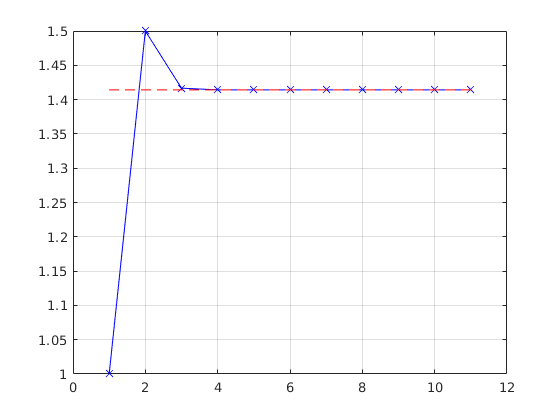

clear; clc;
a(1) = 1;
for ii = 1:10
  a(ii+1) = a(ii)/2 + 1/a(ii);
end
figure;
plot(1:numel(a), a, 'x-b')
hold on,  plot(1:numel(a), sqrt(2)+0*a, 'r--')
grid on